## Project 2: Calculating Values at Risk

### 1.

V = readtable('dat_intel.csv');
X = log(V.Close(2:end)) - log(V.Close(1:end-1));

### 2.

Plot the (sample) autocorrelation and partial autocorrelation functions of X for lags h = 0,...,50

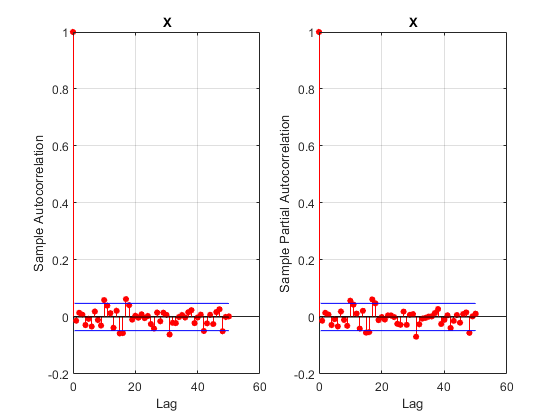

subplot(1,2,1)
autocorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])

subplot(1,2,2)
parcorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])

do a Ljung–Box test with h = 50 for X

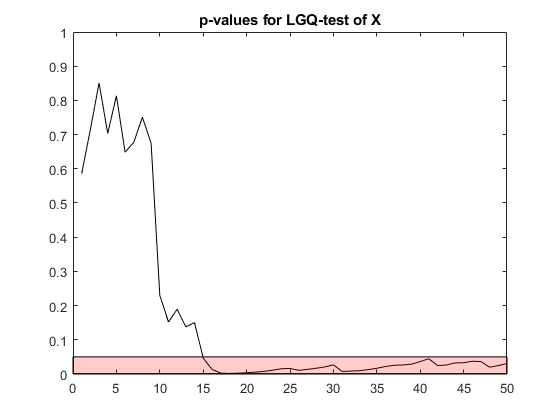

subplot(1,1,1)
resX = X - mean(X);
lags = 1:50;
[h, pValue, stat, cValue] = lbqtest(resX, 'lags', lags);

p = plot(lags, pValue, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) .05 .05 p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('p-values for LGQ-test of X')

Repeat these two steps with the squared returns. We start with the (sample) autocorrelation and partial autocorrelation functions of X^2 for lags h = 0,...,50

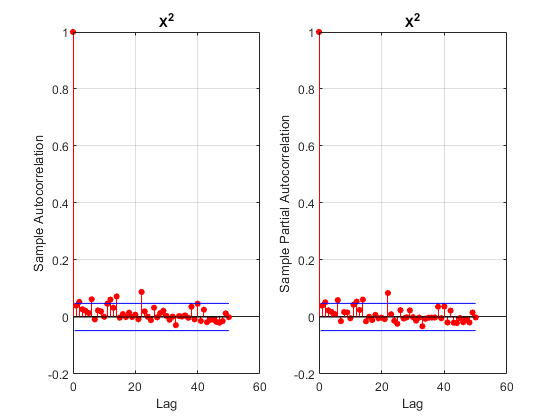

subplot(1,2,1)
autocorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])

subplot(1,2,2)
parcorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])

do a Ljung–Box test with h = 50 for X^2

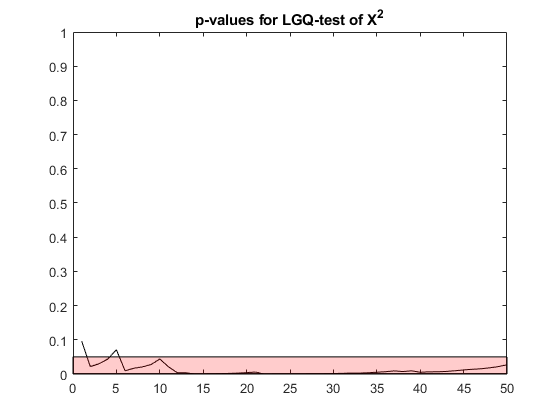

subplot(1,1,1)
resX = X.^2 - mean(X.^2);
lags = 1:50;
[h, pValue, stat, cValue] = lbqtest(resX, 'lags', lags);

p = plot(lags, pValue, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) .05 .05 p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('p-values for LGQ-test of X^2')

#### Discussion

Both $X$ and $X^2$(the squared returns) have outliers on the autocorrelation function plots. They are not very large, but significant enough to be above the 95% confidence interval plotted at a couple of lags, indicating that the series is not entirely white noise. The ljung-box test shows that for $X$, the first 15 lags seem to be white noise, but the remaining lags up to 50, is not. For $X^2$ it is only lag 1 and 5  that comes inside the 95% confidence interval for white noise.

### 3)

Now split the time series $X$ into a training set ($X_t$ , t = 2,...,1526) and a test set ($X_t$ , t = 1527, . . . , 1751).

trainX = X(2:1526);
testX = X(1527:1750);

#### Gaussian distribution

For all values of p and q in the range 0, 1, . . . , 15 and such that p+q > 0 and p ≥ q, fit an ARMA(p, q) process with Gaussian noise to the square returns obtained from the training data and compute the BIC and the AICC (this will take a couple of minutes). Which models minimize the two information criteria? 

i=1;
for p = 1:15
    for q = 0:p
        mdl(i) = arima(p,0,q); 
        i = i + 1;
    end
end

https://se.mathworks.com/help/econ/aicbic.html

for i = 1:size(mdl,2)
    [EstMdl,~,logL(i)] = estimate(mdl(i),X.^2,'Display','off');
    results = summarize(EstMdl);
    numParam(i) = results.NumEstimatedParameters;
end

Note! ic part did not work when using R2020a. Tested and work on R2021a.

[aic,bic,ic] = aicbic(logL,numParam);
[~,minIdx] = structfun(@min,ic);
minIdxChosen = [minIdx(2:3)];
[mdl(minIdxChosen).Description]'

ans = 2×1 string array
    "ARIMA(15,0,4) Model (Gaussian Distribution)"
    "ARIMA(15,0,4) Model (Gaussian Distribution)"


bestmdlGaussian = mdl(minIdx(2));

According to hints and notes: 

*•Compute the BIC and AICC using the formulas given in Methods 3.2.22 and 3.2.23 of the lecture notes. Think of replacing the quantity p + q + 1 by the number M of (non-zero) parameters actually estimated by the algorithm. *

So using aicbic might not be the way they want us to get it. This could maybe be used if our own formulas is correct or not.

#### Student’s *t distribution*

i=1;
for p = 1:15
    for q = 0:p
        mdl(i) = arima(p,0,q); 
        mdl(i).Distribution="t";
        i = i + 1;
    end
end

for i = 1:size(mdl,2)
    try
        [EstMdl,~,logL(i)] = estimate(mdl(i),X.^2,'Display','off');
        results = summarize(EstMdl);
        numParam(i) = results.NumEstimatedParameters;
    catch
        disp("error")
        disp(mdl(i).Description)
        disp("")
    end
end

[aic,bic,ic] = aicbic(logL,numParam);
[~,minIdx] = structfun(@min,ic);
minIdxChosen = [minIdx(2:3)];
[mdl(minIdxChosen).Description]'

ans = 2×1 string array
    "ARIMA(12,0,12) Model (t Distribution)"
    "ARIMA(12,0,12) Model (t Distribution)"


bestmdlT = mdl(minIdx(2));

EstMdlG = estimate(bestmdlGaussian,X.^2)

 
    ARIMA(15,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00021746     4.6523e-05         4.6742     2.9516e-06
    AR{1}         -0.34787       0.052717        -6.5989      4.143e-11
    AR{2}         -0.38022       0.066213        -5.7424     9.3363e-09
    AR{3}          -0.2563       0.048375        -5.2983     1.1691e-07
    AR{4}          0.59732       0.071458          8.359     6.3255e-17
    AR{5}         0.011334       0.044259        0.25609        0.79788
    AR{6}         0.046009       0.037554         1.2251        0.22052
    AR{7}        0.0071068

EstMdlG =   arima with properties:

     Description: "ARIMA(15,0,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 15
               D: 0
               Q: 4
        Constant: 0.000217457
              AR: {-0.347874 -0.380218 -0.256303 0.597318 0.0113341 0.0460086 0.00710679 0.0270129 0.0303984 -0.0358368 0.0469482 0.0667757 0.0433071 0.108009 0.0252609} at lags [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
             SAR: {}
              MA: {0.376222 0.433418 0.3127 -0.552976} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.35132e-07

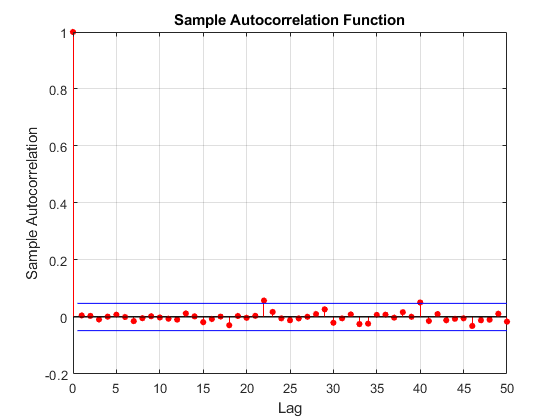


[resG, v] = infer(EstMdlG, X.^2);
sresG = resG./sqrt(v);
autocorr(sresG,'NumLags',50)

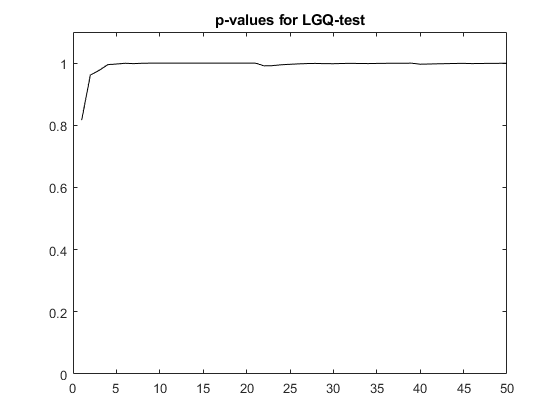

lags = 1:50;
[h, pValue, stat, cValue] = lbqtest(sresG, 'lags', lags);
p = plot(lags, pValue, 'k');
ylim([0, 1.1])
title('p-values for LGQ-test')

EstMdlT = estimate(bestmdlT,X.^2)

 
    ARIMA(12,0,12) Model (t Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     4.947e-06     5.0126e-06        0.98691        0.32369
    AR{1}        -0.041333        0.56496      -0.073162        0.94168
    AR{2}         -0.19715        0.36735       -0.53667         0.5915
    AR{3}         -0.14995        0.42345       -0.35411        0.72326
    AR{4}          0.11647         0.1735        0.67133        0.50201
    AR{5}        -0.021306         0.1934       -0.11017        0.91228
    AR{6}        -0.046348        0.16205         -0.286        0.77487
    AR{7}          0.61359      

EstMdlT =   arima with properties:

     Description: "ARIMA(12,0,12) Model (t Distribution)"
    Distribution: Name = "t", DoF = 2.02125
               P: 12
               D: 0
               Q: 12
        Constant: 4.94699e-06
              AR: {-0.0413333 -0.197148 -0.149946 0.116475 -0.0213062 -0.0463485 0.613595 0.112 0.367364 0.0974365 -0.00252793 -0.00538931} at lags [1 2 3 4 5 6 7 8 9 10 11 12]
             SAR: {}
              MA: {0.0389397 0.201538 0.158051 -0.114414 0.0252517 0.0482283 -0.614212 -0.110425 -0.36539 -0.101918 0.0100072 0.0208357} at lags [1 2 3 4 5 6 7 8 9 10 11 12]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 7.32112e-07

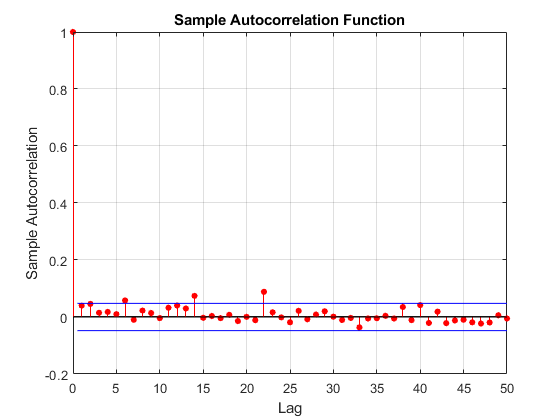


[resT, v] = infer(EstMdlT, X.^2);
sresT = resT./sqrt(v);
autocorr(sresT,'NumLags',50)

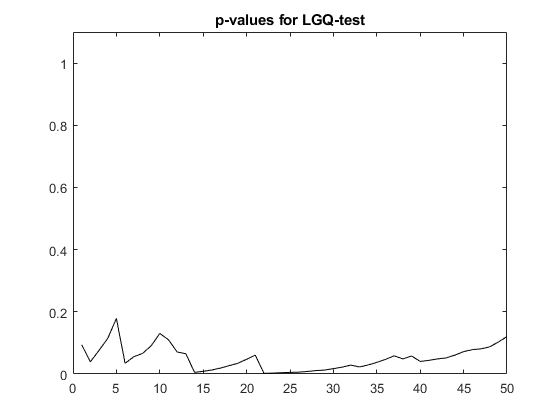

[h, pValue, stat, cValue] = lbqtest(sresT, 'lags', lags);
p = plot(lags, pValue, 'k');
ylim([0, 1.1])
title('p-values for LGQ-test')